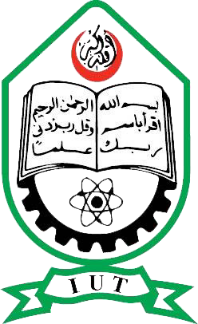

Islamic University of Technology

Name                          : Shazzad Ahmed 

Student ID                   : 220021108 

Section                        : A-(02) 

Department                 :EEE 

Course No                    : EEE-4416

Course Title                 : Matlab Simulation Lab

Experiment No            : 9

Date of Submission    : 17/08/2025

**Exercise - 01**

summary(cirrhosis);

Variables:

    N_Days: 418×1 double

        Values:

            Min           41  
            Median      1730  
            Max         4795  

    Status: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Drug: 418×1 double

        Values:

            Min          0    
            Median       1    
            Max          2    

    Age: 418×1 double

        Values:

            Min         9598  
            Median     18628  
            Max        28650  

    Sex: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Ascites: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Hepatomegaly: 418×1 double

        Values:

     

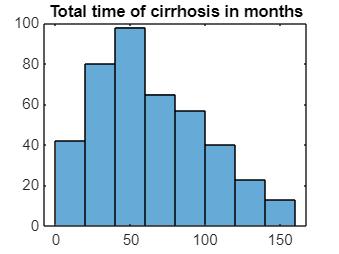

histogram(cirrhosis.N_Days/30);
title('Total time of cirrhosis in months');

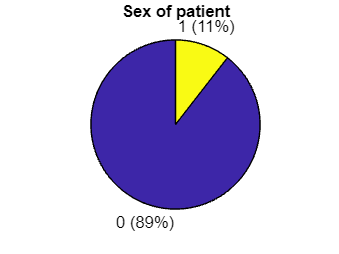

pie(categorical(cirrhosis.Sex));
title('Sex of patient');

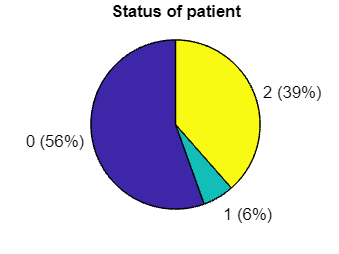

pie(categorical(cirrhosis.Status));
title('Status of patient');

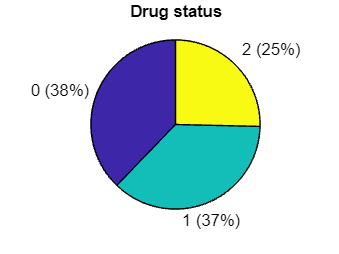

pie(categorical(cirrhosis.Drug));
title('Drug status');

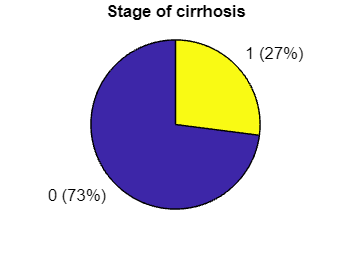

pie(categorical(cirrhosis.Stage));
title('Stage of cirrhosis');

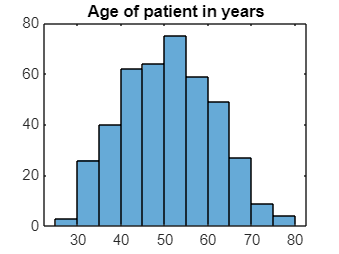

histogram(cirrhosis.Age/365);
title('Age of patient in years');

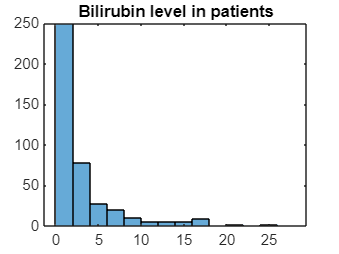

histogram(cirrhosis.Bilirubin);
title('Bilirubin level in patients');

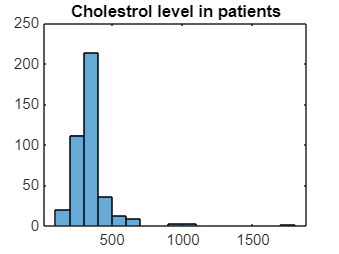

histogram(cirrhosis.Cholesterol);
title('Cholestrol level in patients');

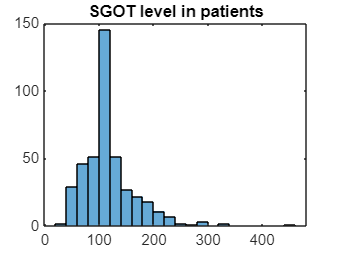

histogram(cirrhosis.SGOT);
title('SGOT level in patients');

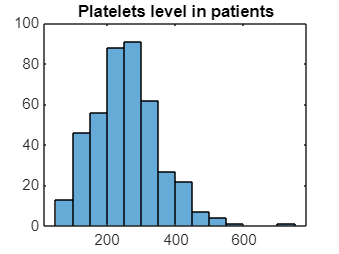

histogram(cirrhosis.Platelets);
title('Platelets level in patients');

**Exercise - 02**

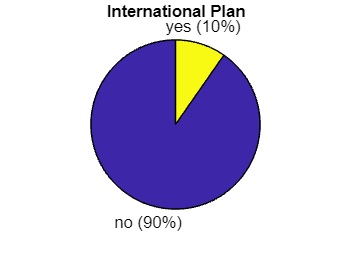

pie(BigMLDataset.internationalPlan);
title('International Plan');

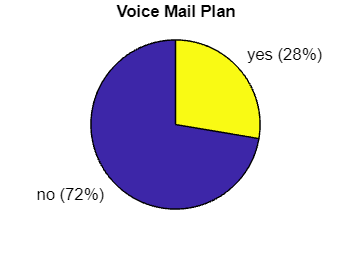

pie(BigMLDataset.voiceMailPlan);
title('Voice Mail Plan');

pie(BigMLDataset.voiceMailPlan);
title('Voice Mail Plan');

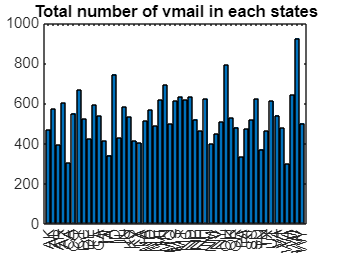

vmail = groupsummary(BigMLDataset, "state", "sum", "numberVmailMessages");
bar(vmail{:,1},vmail{:,3});
title("Total number of vmail in each states");

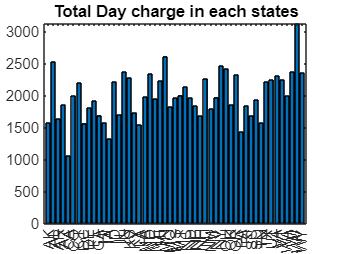

daycharge = groupsummary(BigMLDataset, "state", "sum", "totalDayCharge");
bar(daycharge{:,1},daycharge{:,3});
title("Total Day charge in each states");

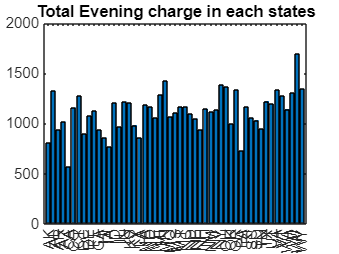

evecharge = groupsummary(BigMLDataset, "state", "sum", "totalEveCharge");
bar(evecharge{:,1},evecharge{:,3});
title("Total Evening charge in each states");

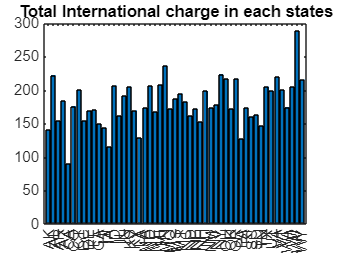

intlcharge = groupsummary(BigMLDataset, "state", "sum", "totalIntlCharge");
bar(intlcharge{:,1},intlcharge{:,3});
title("Total International charge in each states");

**Exercise - 03**

fatalpoliceshootingsdata.year = year(fatalpoliceshootingsdata.date);
unarmed_data = fatalpoliceshootingsdata(fatalpoliceshootingsdata.armed_with == 'unarmed',:)

unarmed_data = 557×20 table
    id        date       threat_type    flee_status    armed_with         city             county       state    latitude    longitude    location_precision              name               age    gender    race     race_source     was_mental_illness_related    body_camera    agency_ids    year
    ___    __________    ___________    ___________    __________    _______________    ____________    _____    ________    _________    __________________

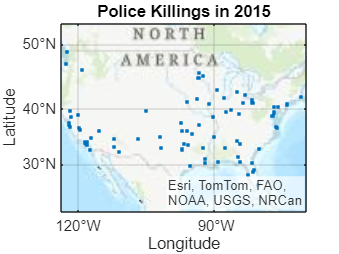

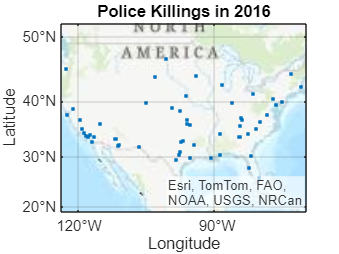

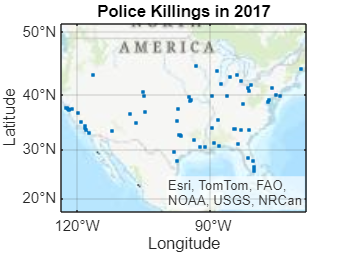

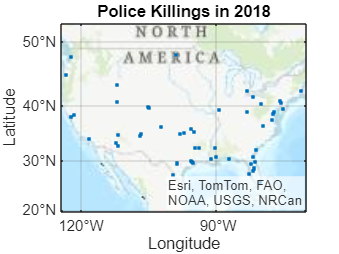

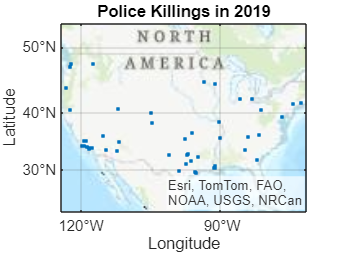

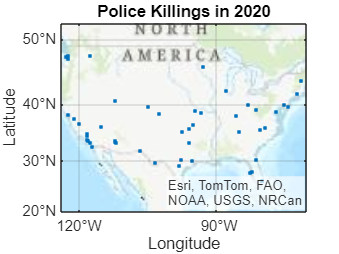

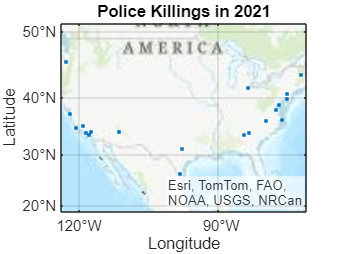

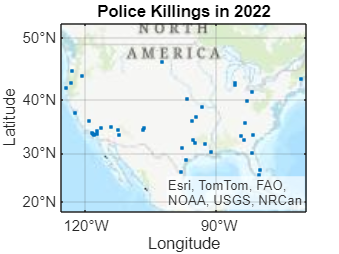

lat_min = 24.396308;
lat_max = 49.384358;
lon_min = -125.0;
lon_max = -66.93457;
in_usa = (unarmed_data.latitude >= lat_min) & (unarmed_data.latitude ...
 <= lat_max) & (unarmed_data.longitude >= lon_min) & ...
 (unarmed_data.longitude <= lon_max);
df= unarmed_data(in_usa,:);
filename = 'unarmed police shootings.gif';
years= 2015:2022;
for i = 1:length(years)
 currentYear = years(i);
 subset = df(df.year == currentYear, :);
 figure;
 geoscatter(subset.latitude, subset.longitude, '.');
 geobasemap topographic
 title(sprintf('Police Killings in %d', currentYear));
 frame = getframe(gcf);
 im = frame2im(frame);
 [imind, cm] = rgb2ind(im, 256);
 if i == 1
 imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 1);
 else
 imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 1);
 end
 pause(1);
end

**Exercise - 04**

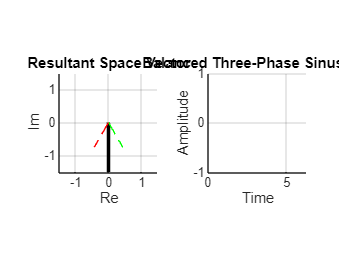

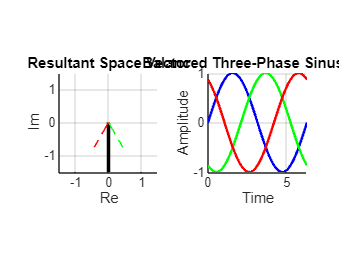

t = linspace(0, 2*pi, 300);
f = 1;
u = sin(t);
v = sin(t - 2*pi/3);
w = sin(t + 2*pi/3);
vec = u + v*exp(1j*2*pi/3) + w*exp(-1j*2*pi/3);
video = VideoWriter('Balanced Three Phase Sinusoids.mp4','MPEG-4'); 
video.FrameRate = 30; 
open(video);
figure('Color','w');
for k = 1:length(t)
 clf;
 subplot(1,2,1);
 hold on; 
 axis equal; 
 grid on;
 xlabel('Re'); 
 ylabel('Im');
 title('Resultant Space Vector');
 xlim([-1.5 1.5]); 
 ylim([-1.5 1.5]);
 plot([0 real(vec(k))],[0 imag(vec(k))],'k','LineWidth',2);
 plot([0 u(k)], [0 0],'b--');
 plot([0 v(k)*cos(2*pi/3)], [0 v(k)*sin(2*pi/3)],'g--');
 plot([0 w(k)*cos(-2*pi/3)], [0 w(k)*sin(-2*pi/3)],'r--');
 
 subplot(1,2,2);
 hold on; 
 grid on;
 xlabel('Time'); 
 ylabel('Amplitude');
 title('Balanced Three-Phase Sinusoids');
 xlim([0 max(t)]); 
 ylim([-1 1]);
 pbaspect([1 1 1])
 plot(t(1:k),u(1:k),'b','LineWidth',1.5);
 plot(t(1:k),v(1:k),'g','LineWidth',1.5);
 plot(t(1:k),w(1:k),'r','LineWidth',1.5);
 
 frame = getframe(gcf);
 writeVideo(video, frame);
end

close(video);

**Exercise - 05**

weatherdata = readtable('weatherdata.csv','TextType','string');

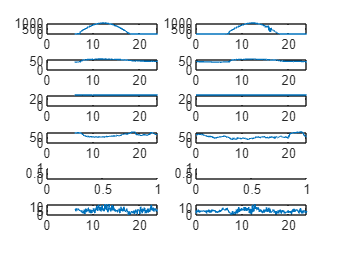


if ~isdatetime(weatherdata.Data), weatherdata.Data = ...
    datetime(string(weatherdata.Data)); end
if ~isdatetime(weatherdata.Time), weatherdata.Time = ...
    datetime(string(weatherdata.Time)); end

T29 = weatherdata(day(weatherdata.Data) == 29,:);
T28 = weatherdata(day(weatherdata.Data) == 28,:);

T29Hours = hours(timeofday(T29.Time));
T28Hours = hours(timeofday(T28.Time));

xmin = 0; xmax = 24; filename = 'Change_of_variables_with_time.gif';
fig = figure('Renderer','painters');

getmax = @(x) max(x,[],'omitnan');

for i = linspace(xmin, xmax, 24)
    subplot(6,2,1); cla;
    plot(T28Hours(T28Hours<i), T28.Radiation(T28Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T28.Radiation))]);

    subplot(6,2,2); cla;
    plot(T29Hours(T29Hours<i), T29.Radiation(T29Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T29.Radiation))]);

    subplot(6,2,3); cla;
    plot(T28Hours(T28Hours<i), T28.Temperature(T28Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T28.Temperature))]);

    subplot(6,2,4); cla;
    plot(T29Hours(T29Hours<i), T29.Temperature(T29Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T29.Temperature))]);

    subplot(6,2,5); cla;
    plot(T28Hours(T28Hours<i), T28.Pressure(T28Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T28.Pressure))]);

    subplot(6,2,6); cla;
    plot(T29Hours(T29Hours<i), T29.Pressure(T29Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T29.Pressure))]);

    subplot(6,2,7); cla;
    plot(T28Hours(T28Hours<i), T28.Humidity(T28Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T28.Humidity))]);

    subplot(6,2,8); cla;
    plot(T29Hours(T29Hours<i), T29.Humidity(T29Hours<i)); 
    xlim([xmin xmax]); ylim([0 max(1,getmax(T29.Humidity))]);

    subplot(6,2,9); cla;
    if ismember('WindDirectionDegrees',weatherdata.Properties.VariableNames)
        plot(T28Hours(T28Hours<i), T28.WindDirectionDegrees(T28Hours<i)); 
        xlim([xmin xmax]); ylim([0 max(1,getmax(T28.WindDirectionDegrees))]);
    end

    subplot(6,2,10); cla;
    if ismember('WindDirectionDegrees',weatherdata.Properties.VariableNames)
        plot(T29Hours(T29Hours<i), T29.WindDirectionDegrees(T29Hours<i)); 
        xlim([xmin xmax]); ylim([0 max(1,getmax(T29.WindDirectionDegrees))]);
    end

    subplot(6,2,11); cla;
    if ismember('Speed',weatherdata.Properties.VariableNames)
        plot(T28Hours(T28Hours<i), T28.Speed(T28Hours<i)); 
        xlim([xmin xmax]); ylim([0 max(1,getmax(T28.Speed))]);
    end

    subplot(6,2,12); cla;
    if ismember('Speed',weatherdata.Properties.VariableNames)
        plot(T29Hours(T29Hours<i), T29.Speed(T29Hours<i)); 
        xlim([xmin xmax]); ylim([0 max(1,getmax(T29.Speed))]);
    end

    frame = getframe(fig); im = frame2im(frame); [imind, cm] = rgb2ind(im, 256);
    if i == xmin
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.3);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

**Exercise - 06**

%My name is Shazzad. So extracting countries starting with 'S'
countries = char(worldcities.country);
S_countries = worldcities(countries(:,1) == 'S', :);
head(S_countries, 7)

         city           city_ascii        lat        lng        country       iso2    iso3         admin_name           capital      population        id    
    ______________    ______________    _______    _______    ____________    ____    ____    ____________________    ___________    __________    __________

    "Khartoum"        "Khartoum"         15.603     32.526    Sudan            SD     SDN     Khartoum                primary         7.282e+06    1.7293e+09
    "Riyadh"          "Riyadh"            24.65      46.71    Saudi Arabia     SA     SAU     Ar Riyāḑ                primary         6.881e+06     1.6

normalized_popul = (S_countries.population/(max(S_countries.population)- min(S_countries.population)))*100

normalized_popul =   100.0001
   94.4933
   78.8932
   63.0047
   60.9013
   54.6004
   44.8521
   38.5251
   29.1129
   25.1867


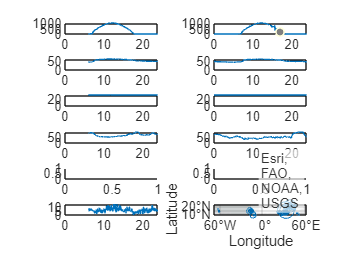

geoscatter(S_countries.lat, S_countries.lng, normalized_popul)

**Exercise - 07**

x = [1,2; 2,1]
z = sort(x, 2);
[a,b] = unique(z, 'rows');
x(b,:)